#### EX 10-1 基于小波分析的图像融合-1层

a = imread('./images/a.tif'); imshow(a)
b = imread('./images/b.tif'); imshow(b)
% 小波分解（使用Haar小波基；1层）
[CA1, CH1, CV1, CD1] = dwt2(a, 'haar');
[CA2, CH2, CV2, CD2] = dwt2(b, 'haar');
% 融合小波系数
CA = (CA1 + CA2) *0.5; % 取低频系数的平均值
CH = max(CH1, CH2); % 取高频系数的最大值
CV = max(CV1, CV2);
CD = max(CD1, CD2);
% 小波重构
y = idwt2(CA, CH, CV, CD, 'haar');
% 显示融合后的图像
imshow(y, []);

**EX 10-2 基于小波分析的图像融合-2层**

a = imread('./images/a.tif'); imshow(a)
b = imread('./images/b.tif'); imshow(b)
% 小波分解 （使用Haar小波基；2层）
[ca,sa] = wavedec2(im2double(a),2,'haar'); 
[cb,sb] = wavedec2(im2double(b),2,'haar');
% 小波融合
yc = zeros(size(cb)); % 初始化用于存储融合后小波系数的数组
m = sb(1,1)*sb(1,2); % 单层分解近似系数的长度（区分高低频）
MM1 = ca(m+1:end); % 提取图像1的高频系数
MM2 = cb(m+1:end); % 提取图像2的高频系数
yc(1:m) = (ca(1:m)+cb(1:m))/2; % 两个图像的低频系数取平均
mm = abs(MM1) > abs(MM2); % 选高频系数绝对值大的
yc(m+1:end) = mm.*MM1 + (~mm).*MM2;
% 小波重构
y = waverec2(yc, sa, 'haar');
imshow(y)

**EX 10-3 图像全景拼接**

img1 = imread('./images/img1.jpg'); imshow(img1); title("图1")
img2 = imread('./images/img2.jpg'); imshow(img2); title("图2")
% 转换为灰度图像以便于特征检测
grayImg1 = rgb2gray(img1); grayImg2 = rgb2gray(img2);
% 使用SURF算法检测特征点
points1 = detectSURFFeatures(grayImg1);
points2 = detectSURFFeatures(grayImg2);
% 提取特征点周围的特征
[features1, valid_points1] = extractFeatures(grayImg1, points1);
[features2, valid_points2] = extractFeatures(grayImg2, points2);
% 匹配特征点
indexPairs = matchFeatures(features1, features2);
% 检索匹配点的位置
matchedPoints1 = valid_points1(indexPairs(:, 1), :);
matchedPoints2 = valid_points2(indexPairs(:, 2), :);
% 使用RANSAC算法估计几何变换矩阵
[tform, ~] = estimateGeometricTransform2D(matchedPoints2, matchedPoints1, ...
    'projective', 'Confidence', 99.9, 'MaxNumTrials', 2000);
% 计算变换后的图片大小
imageSize = size(img1);
[xlim, ylim] = outputLimits(tform, [1 imageSize(2)], [1 imageSize(1)]);
% 找出拼接图像的范围
xMin = min([1; xlim(:)]);  xMax = max([imageSize(2); xlim(:)]);
yMin = min([1; ylim(:)]);  yMax = max([imageSize(1); ylim(:)]);
% 初始化全景图像
width  = round(xMax - xMin);  height = round(yMax - yMin);
panorama = zeros([height width 3], 'like', img1);
% 创建变换器
blender = vision.AlphaBlender('Operation', 'Binary mask', 'MaskSource', 'Input port');
% 对第一张图像进行变换，填充全景图像
xLimits = [xMin xMax];  yLimits = [yMin yMax];
panoramaView = imref2d([height width], xLimits, yLimits);
% 将第一张图像放置在全景图中，无需变换
panorama = step(blender, panorama, img1, img1(:,:,1)>0);
% 对第二张图像进行变换，填充全景图像
warpedImage = imwarp(img2, tform, 'OutputView', panoramaView);
panorama = step(blender, panorama, warpedImage, warpedImage(:,:,1)>0);
panorama(:, all(all(panorama == 0, 1), 3), :) = []; % 删除所有全黑列
imshow(panorama); title("全景拼接结果") % 显示全景图像


**EX 10-4 光流法**

注意运行时，在目录下是否已存在movie OF.avi，如存在需要修改为其它名称再运行。

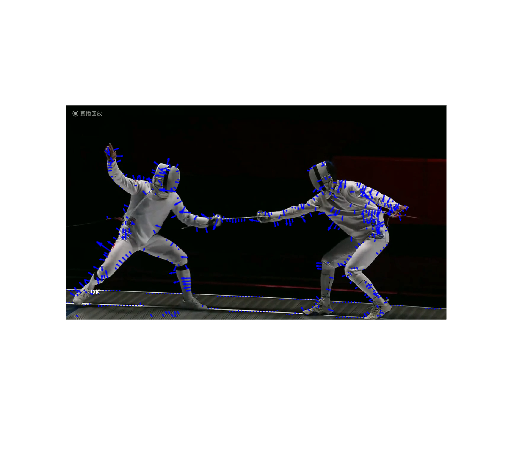

% 设置输入视频和输出视频的路径
inputVideoPath = fullfile('images', 'movie.avi');
outputVideoPath = fullfile('images', 'movie OF.avi');
% 创建一个VideoReader来读取视频
videoReader = VideoReader(inputVideoPath);
% 创建一个VideoWriter来保存带有光流的输出视频
videoWriter = VideoWriter(outputVideoPath, 'Motion JPEG AVI');
% 打开视频文件进行写入
open(videoWriter);
% 创建光流对象，这里使用Lucas-Kanade方法
opticFlow = opticalFlowLK('NoiseThreshold', 0.009);
% 逐帧处理视频
while hasFrame(videoReader)
    % 读取一帧
    frameRGB = readFrame(videoReader);
    frameGray = rgb2gray(frameRGB); % 转换为灰度图像
    % 计算光流
    flow = estimateFlow(opticFlow, frameGray); 
    % 在原始帧上绘制光流向量
    imshow(frameRGB);
    hold on;
    plot(flow, 'DecimationFactor', [10 10], 'ScaleFactor', 15);
    hold off;
    % 获取当前帧的绘图
    frameWithFlow = getframe(gca);
    % 将绘制了光流的帧写入输出视频
    writeVideo(videoWriter, frameWithFlow.cdata);
end

close(videoWriter); disp('完成.') % 关闭视频文件

完成.
